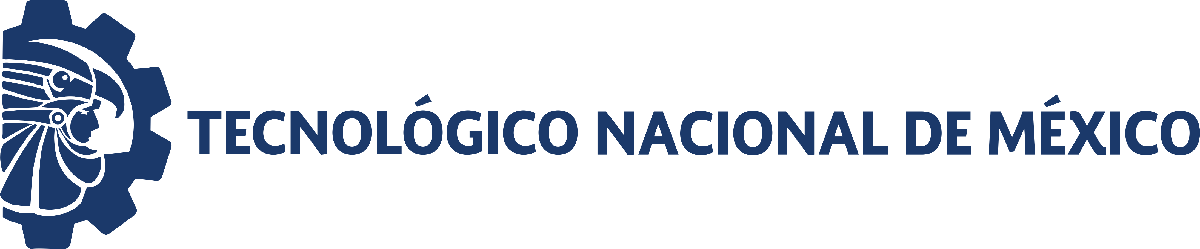                                 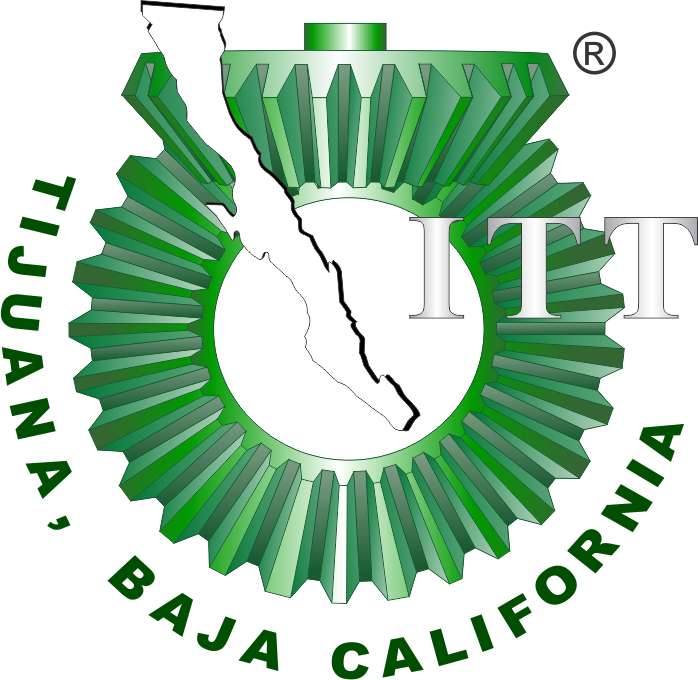

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

# Proyecto: Dinámica metabólica

## Información general

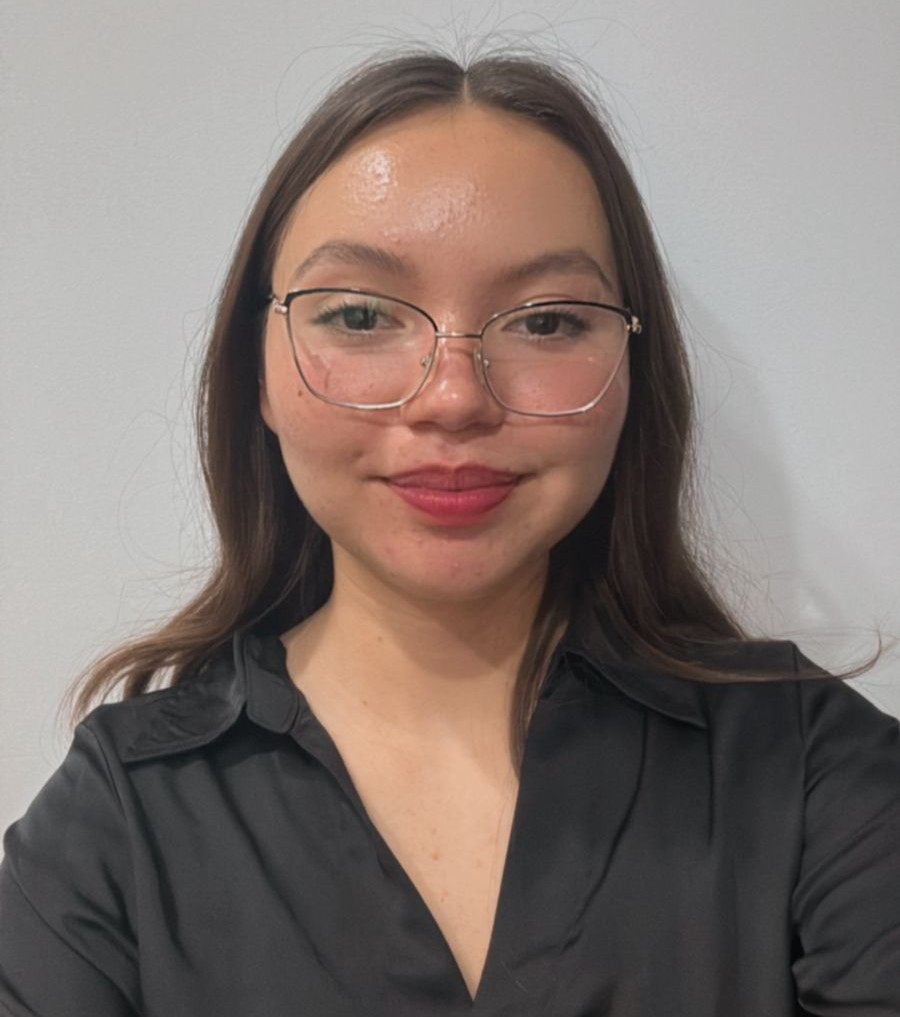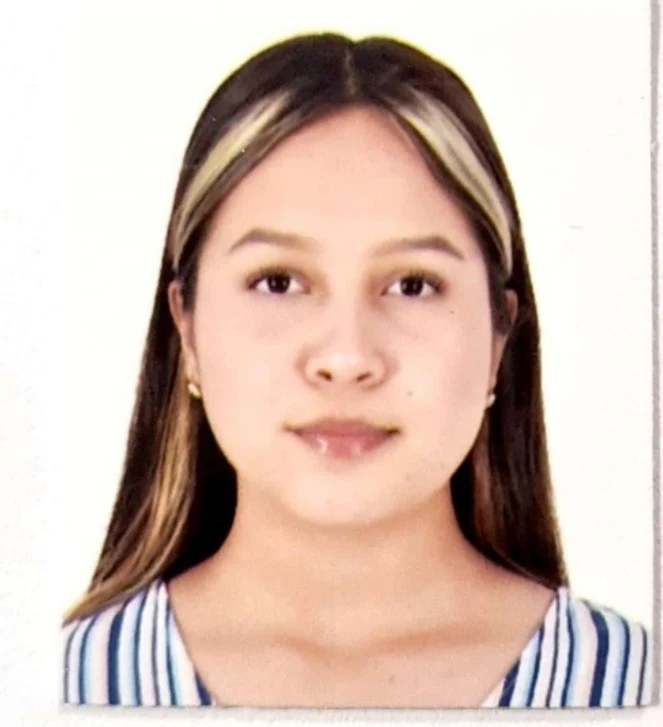

Nombre del alumno: **Sofía Cristina Durán Muñoz;** **Karla Emilia Silva Pérez**

Número de control: ** 22211752; 22211767**

Correo institucional:  **l22211752@tectijuana.edu.mx; l22211767@tectijuana.edu.mx**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## **Descripción**

    Este proyecto consiste en el desarrollo de un **Gemelo Digital** diseñado para replicar el comportamiento dinámico de una cascada metabólica celular. El sistema se basa en un conjunto de variables biológicas y su evolución en el tiempo, que rastrea la evolución temporal de tres componentes clave: un *sustrato inicial* (${\mathit{\mathbf{x}}}_3$), un *intermediario metabólico* (${\mathit{\mathbf{y}}}_3$) y un* producto final* (${\mathit{\mathbf{z}}}_3$).

### Objetivo

    Desarrollar un Gemelo Digital predictivo de una cascada metabólica celular a partir de datos experimentales, utilizando un sistema de ecuaciones diferenciales ordinarias ajustado mediante regresión no lineal, para validar y simular la dinámica de autorregulación del sistema.

### Modelo experimental

    El sistema simula una ruta de biosíntesis donde el flujo de masa sigue una secuencia lógica ($x\to y\to z$). La característica distintiva de este modelo es su mecanismo de control por** retroalimentación negativa **(*Feedback Inhibition*). En este proceso, la acumulación del producto final ($z$) inhibe la velocidad de entrada del sustrato inicial mediante una **cinética de Hill**. Este comportamiento es fundamental para la supervivencia celular, ya que permite mantener la homeostasis y evitar el desperdicio de recursos energéticos.

#### Arquitectura del modelo matemático

    El sistema se rige por un conjunto de tres **Ecuaciones Diferenciales Ordinarias (EDOs)** que describen las tasas de cambio de cada componente basándose en interacciones directas:

**Dinámica del Sustrato (**$x$**): **


$$\dot{x} =a_1 x\;z-a_2 x$$


La tasa de cambio del sustrato depende positivamente de la presencia del producto $z$ (catalizada por el parámetro $k_1$), enfrentando una tasa de consumo basal constante representada por $k_2$.

**Dinámica del Intermediario (**$y$**):**

 
$$\dot{y} =b_1 y\;z-b_2 y$$


La formación del intermediario es el resultado de la interacción o sinergia biológica entre el sustrato $x$ y el producto $z$, cuantificada por la constante cinética $k_3$. A su vez, presenta una tasa de pérdida constante $k_4 \ldotp$

Dinámica del Producto ($z$):

 
$$\dot{z} =-k_3 z$$


El producto se genera directamente a partir del intermediario $y$ (con velocidad $k_5$) y sufre una degradación o salida del sistema proporcional a su propia concentración, dictada por la constante $k_6$.

#### Parámetros 

La calibración del Gemelo Digital exige la identificación de **seis parámetros cinéticos **($k_1$ a $k_6$):

- $k_1$**, **$k_3$**, **$k_5$**:** Constantes cinéticas de producción, que miden la eficiencia con la que los componentes del sistema estimulan la síntesis de nuevas moléculas.

- $k_2$**, **$k_4$**:** Términos de consumo basal (orden cero) para el sustrato y el intermediario.

- $k_6$**:** Constante de degradación o consumo de primer orden para el producto final.

#### Metodología de ajuste 

Para parametrizar este modelo con base experimental, se integró el sistema de ecuaciones diferenciales utilizando el **Método de Heun **con un algoritmo de regresión no lineal para estimar los seis parámetros ($k_1$ ... $k_6$). Este proceso minimiza el error entre la predicción computacional y los datos reales, validando estadísticamente las constantes encontradas.

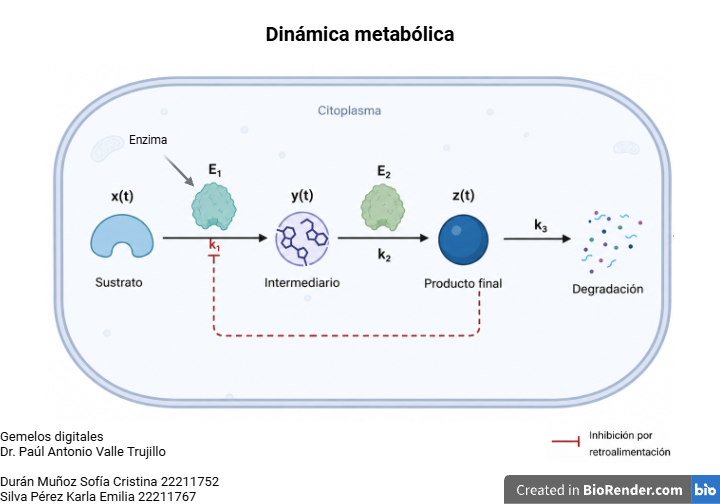

Figura 1. Diagrama biológico de la cascada metabólica con [https://www.biorender.com/](https://www.biorender.com/).

## Referencias

[1] Valle, Paul A., Syllabus para Biología de Sistemas y Gemelos Digitales, Tecnológico Nacional de México / Instituto Tecnológico de Tijuana, Tijuana, B.C., México, 2026. Permalink: [https://biomath.xyz/course/](https://biomath.xyz/course/) 

[2] Garfinkel, Alan, Jane Shevtsov, and Yina Guo. Modeling life: the mathematics of biological systems. Springer International Publishing AG, 2017.

## Datos experimentales: Todos los conjuntos

cd('C:\Users\karla\OneDrive\Desktop\gemelos\P')

clc; clear; close all; warning('off')
sys = readmatrix('data.csv');

t  = round(sys(:,1));
x1 = sys(:,2);
y1 = sys(:,3);
z1 = sys(:,4);
x2 = sys(:,5);
y2 = sys(:,6);
z2 = sys(:,7);
x3 = sys(:,8);
y3 = sys(:,9);
z3 = sys(:,10);

Tabla_Datos = table(t,x1,y1,z1,x2,y2,z2,x3,y3,z3);
disp(Tabla_Datos)

    t       x1        y1        z1       x2        y2       z2       x3       y3       z3  
    __    ______    ______    ______    _____    ______    _____    _____    _____    _____

     0     5.596      14.8    109.84    0.517    19.939    0.281    6.423     1.72    6.319
     7    11.975    12.135    100.18     0.58    19.578    0.609    6.752    2.224    6.228
    14    29.188     7.048    68.925    0.726    18.678    1.063    7.414    2.873    6.043
    21    48.982     3.126    29.523    0.965    16.215    1.758    7.852    3.467    5.832
    28     57.75     1.786     9.812    1.282    14.005    2.752     8.15    4.126    5.682
    35    60.27

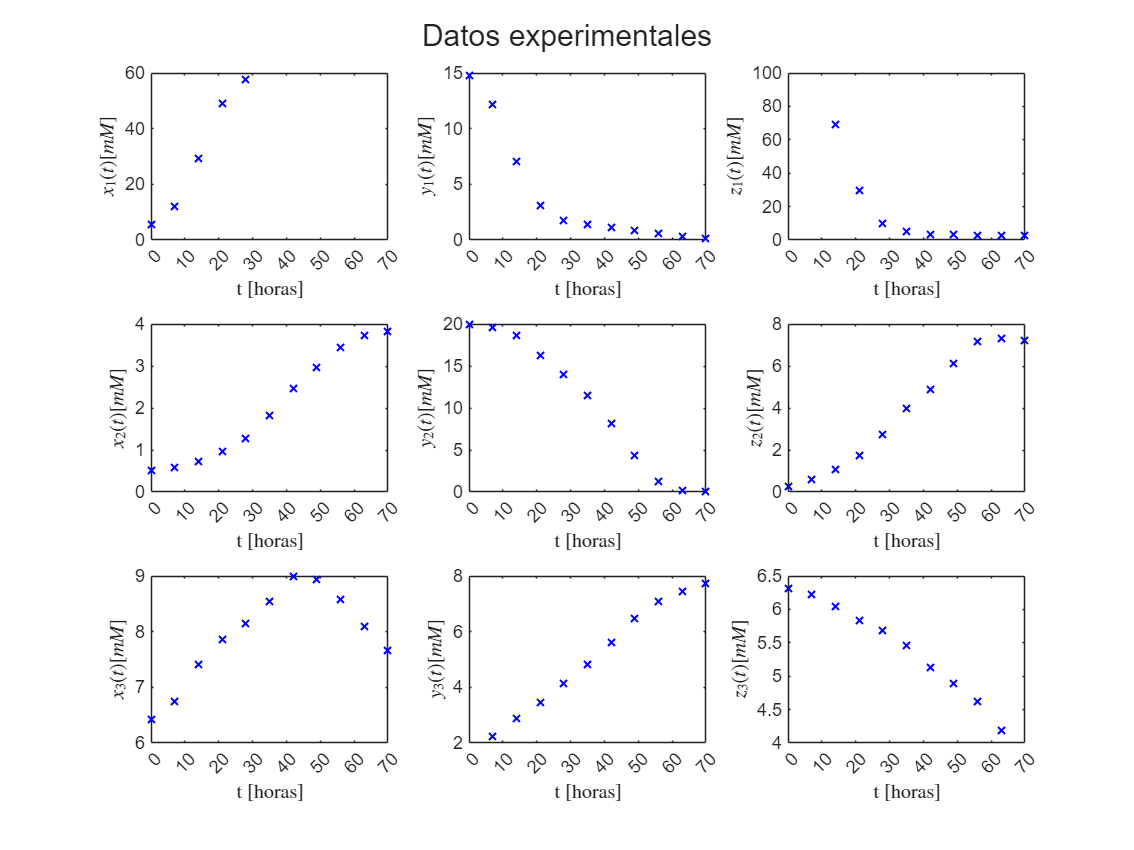

plotsys(t,x1,y1,z1,x2,y2,z2,x3,y3,z3);

sgtitle('Datos experimentales');...
    exportgraphics(gcf,'data.pdf','ContentType','vector')

## Datos experimentales: Conjunto 3

clc; clear; close all; warning('off')
sys = readmatrix('data.csv');
t  = round(sys(:,1));
x3 = sys(:,8);
y3 = sys(:,9);
z3 = sys(:,10);
 
Tabla_Datos = table(t,x3,y3,z3);
disp(Tabla_Datos)

    t      x3       y3       z3  
    __    _____    _____    _____

     0    6.423     1.72    6.319
     7    6.752    2.224    6.228
    14    7.414    2.873    6.043
    21    7.852    3.467    5.832
    28     8.15    4.126    5.682
    35    8.548    4.815    5.456
    42    8.997    5.615     5.13
    49     8.94    6.476    4.892
    56    8.581    7.091    4.615
    63    8.099    7.457    4.188
    70    7.661    7.715    3.911



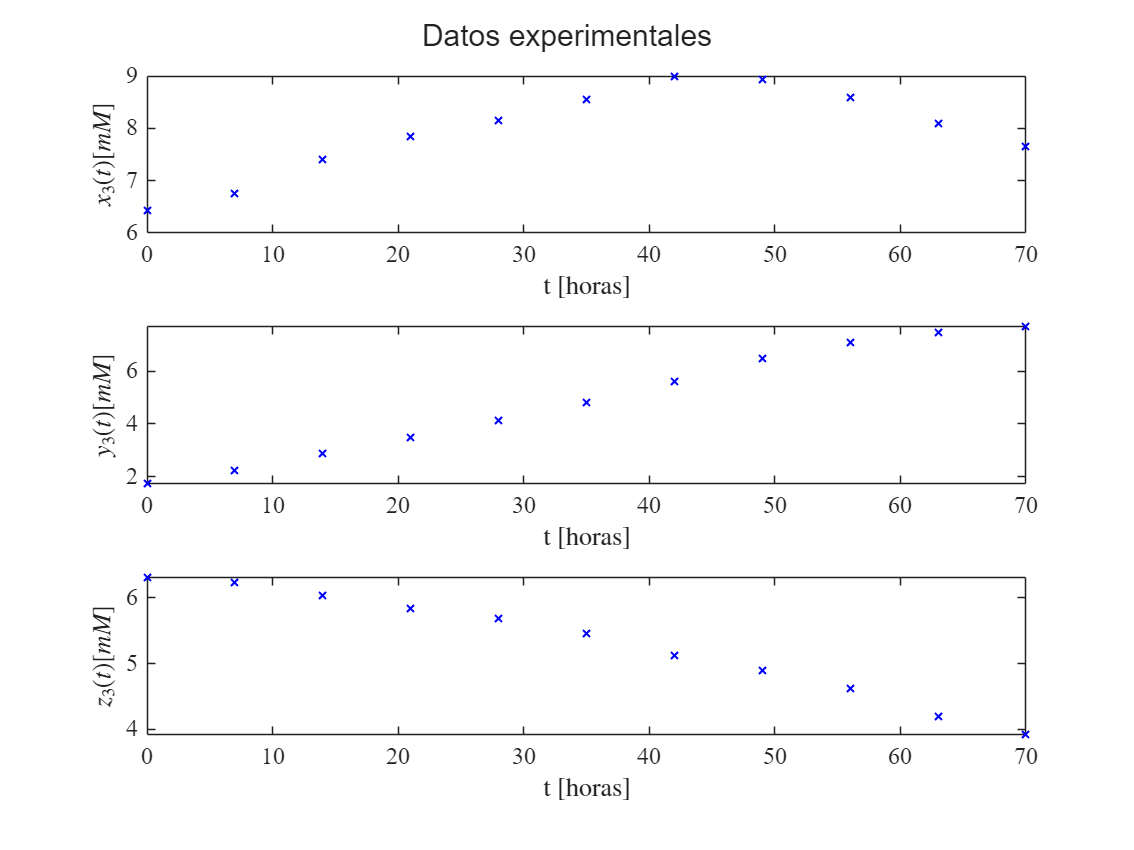

plotsys3(t,x3,y3,z3);
sgtitle('Datos experimentales');...
    exportgraphics(gcf,'data_raw.pdf','ContentType','vector')

## Procesamiento de datos

### Datos suavizados

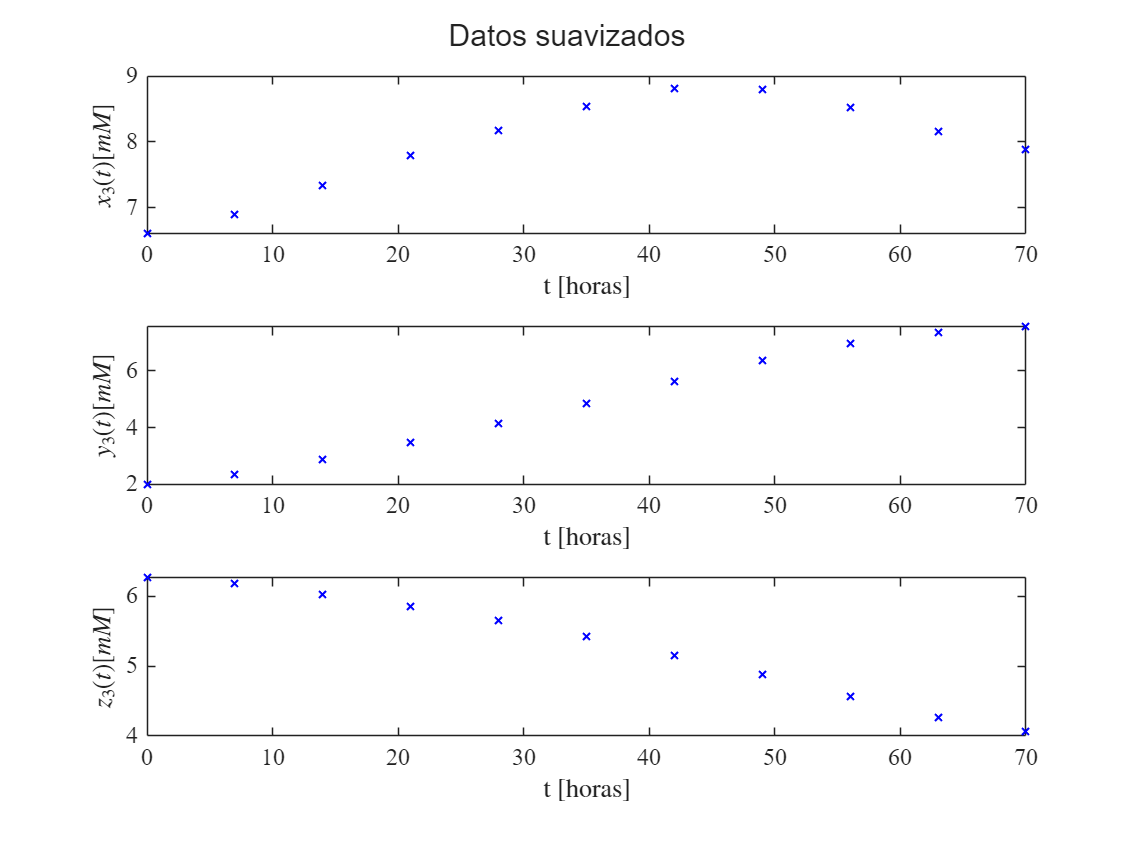

smooth = true; normalize = false;
[to,x3o,y3o,z3o] = getdata('data.csv',smooth, normalize);
plotsys3(to,x3o,y3o,z3o); sgtitle('Datos suavizados');...
    exportgraphics(gcf,'data_smooth.pdf','ContentType','vector')

### Datos normalizados

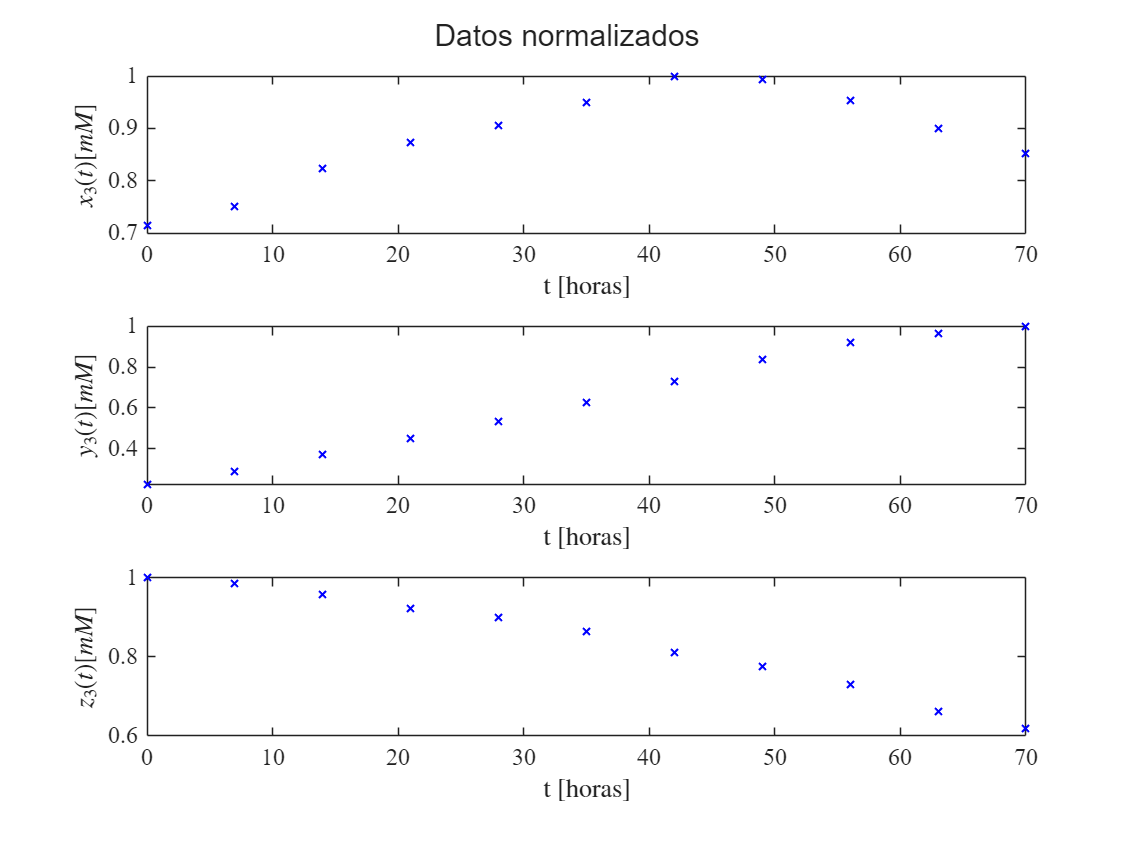

smooth = false; normalize = true;
[to,x3o,y3o,z3o] = getdata('data.csv',smooth, normalize);
plotsys3(to,x3o,y3o,z3o); sgtitle('Datos normalizados');...
    exportgraphics(gcf,'data_normalized.pdf','ContentType','vector')

### Datos suavizados y normalizados

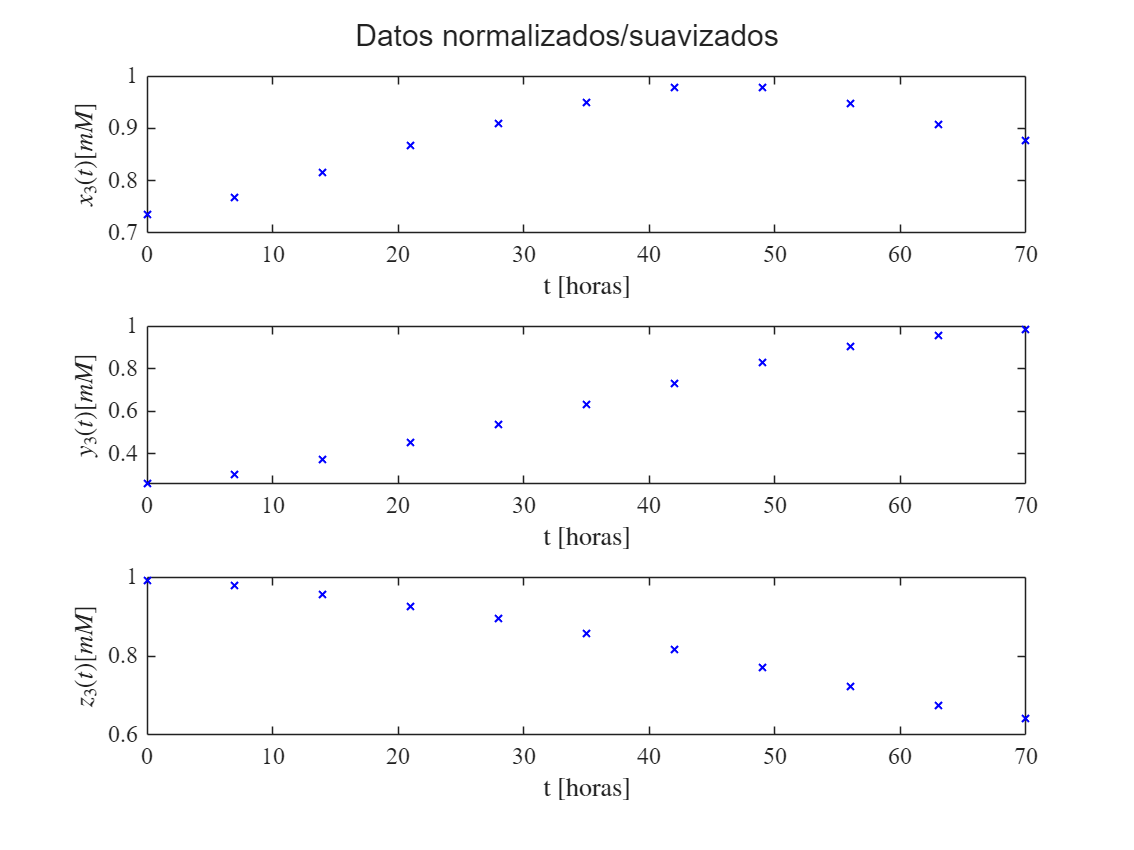

smooth = true; normalize = true;
[to,x3o,y3o,z3o] = getdata('data.csv',smooth, normalize);
plotsys3(to,x3o,y3o,z3o); sgtitle('Datos normalizados/suavizados');...
    exportgraphics(gcf,'data_smooth_normalized.pdf','ContentType','vector')

## Regresión no lineal

clc; clear; close all; warning('off')
sys = readmatrix('data.csv');
t   = round(sys(:,1));
x3  = sys(:,8);
y3  = sys(:,9);
z3  = sys(:,10);

Tabla_Datos = table(t,x3,y3,z3);
disp(Tabla_Datos)

    t      x3       y3       z3  
    __    _____    _____    _____

     0    6.423     1.72    6.319
     7    6.752    2.224    6.228
    14    7.414    2.873    6.043
    21    7.852    3.467    5.832
    28     8.15    4.126    5.682
    35    8.548    4.815    5.456
    42    8.997    5.615     5.13
    49     8.94    6.476    4.892
    56    8.581    7.091    4.615
    63    8.099    7.457    4.188
    70    7.661    7.715    3.911



Po = [0.0090;0.045;0.0135;0.0509;0.005]; % Valores iniciales
biostats = true;
mdl = Variant(t,x3,y3,z3,Po,biostats);

Degrees of freedom: 28
t-student value: 2.0484
Significance value (alpha): 0.05
    Parameters    Estimate         SE           MoE                 CI95               Pvalue  
    __________    _________    __________    __________    ______________________    __________

      {'k1'}       0.010663    0.00094606     0.0019379    0.0087254     0.012601    6.4343e-12
      {'k2'}       0.052947     0.0053969      0.011055     0.041892     0.064002    1.4653e-10
      {'k3'}       0.016839     0.0014503     0.0029708     0.013868      0.01981    3.2293e-12
      {'k4'}       0.066524      0.008212      0.016822     0.049702     0.083345     8.063e-09
      {'k5'}      0.0055549    0.00029519    0.00060467    0.0049502    0.0061595    1.9924e-17


R-cuadrada ordinaria: 0.99165
R-cuadrada 

fa  = mdl.Fitted;
fa  = reshape(fa, [], 3);
x3a = fa(:,1);
y3a = fa(:,2);
z3a = fa(:,3);

plotresults(t,x3,y3,z3,t,x3a,y3a,z3a);
sgtitle('Regresión no lineal', 'Interpreter', 'latex');...
    exportgraphics(gcf, 'data_nonlinear_regression.pdf', 'ContentType', 'vector')

## Prediccion del modelo a 2t

clc; clear; close all; warning('off')
smooth = false; normalize = true;
[to,x3o,y3o,z3o] = getdata('data.csv',smooth,normalize);
Po = [0.0090; 0.045; 0.0135; 0.0509; 0.005];
biostats = false;
mdl = Variant(to,x3o,y3o,z3o,Po,biostats);
par = table2array(mdl.Coefficients(:,1));
a1 = par(1);   
a2 = par(2);   
b1 = par(3);  
b2 = par(4);   
k3 = par(5);  
x0 = x3o(1);
y0 = y3o(1);
z0 = z3o(1);
tend = to(end);
dt = 1E-3;

### Método de Heun

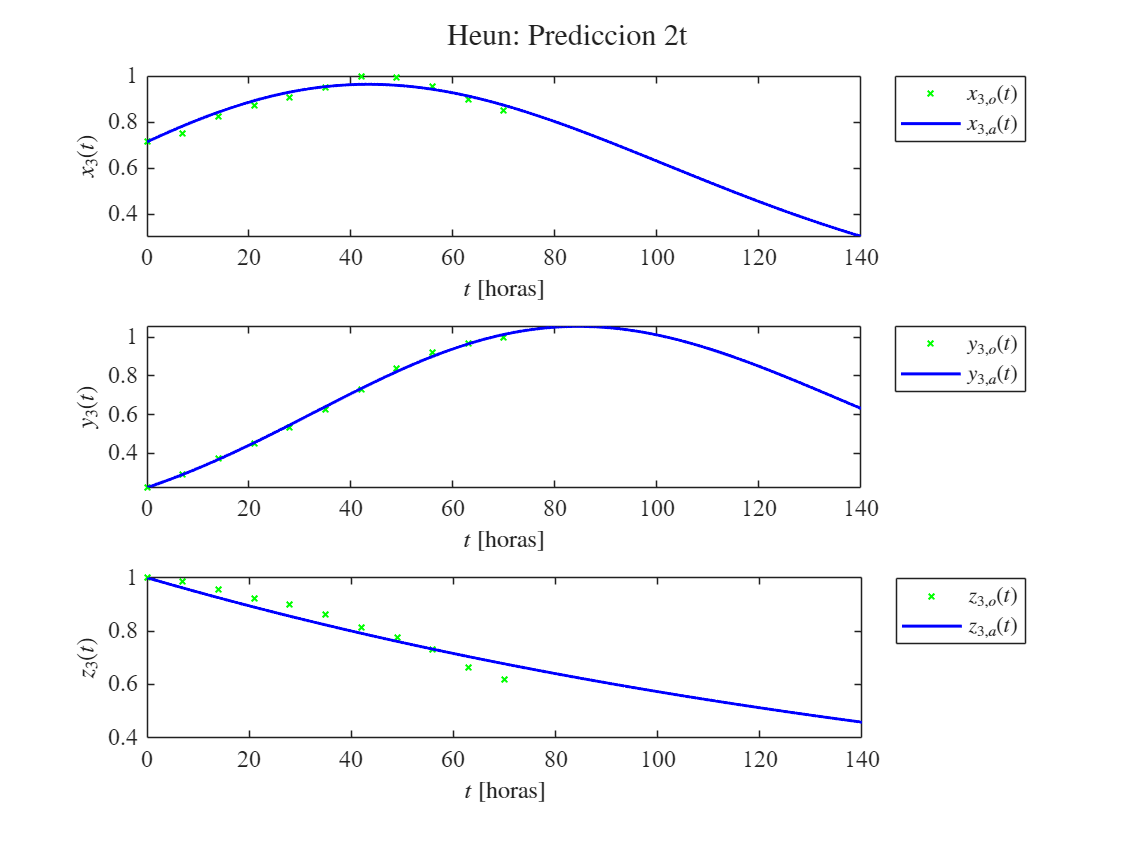

[th,x3h,y3h,z3h] = sysheun(x0,y0,z0,a1,a2,b1,b2,k3,2*tend,dt);
plotresults2(to,x3o,y3o,z3o,th,x3h,y3h,z3h);
sgtitle('Heun: Prediccion 2t','Interpreter','latex')
exportgraphics(gcf,'heun_prediccion2t.pdf','ContentType','vector')

## Puntos de equilibrio

clc; clear
syms x y z a1 a2 b1 b2 k3
dx_dt = a1*x*z - a2*x == 0;
dy_dt = b1*y*z - b2*y == 0;
dz_dt = -k3*z == 0;
fxyz = solve([dx_dt,dy_dt,dz_dt],[x,y,z]);
fprintf('Puntos de equilibrio del sistema: %d\n', length(fxyz.x))

Puntos de equilibrio del sistema: 1


xe_1 = fxyz.x(1); 
ye_1 = fxyz.y(1); 
ze_1 = fxyz.z(1);
fprintf('Punto de equilibrio simbolico:\n')

Punto de equilibrio simbolico:


disp([xe_1, ye_1, ze_1])

$$\left(\begin{array}{ccc} 0 & 0 & 0 \end{array}\right)$$

a1_val=0.0090; a2_val=0.045;
b1_val=0.0135; b2_val=0.0509; k3_val=0.004672;
xe_n = double(subs(xe_1,[a1,a2,b1,b2,k3],[a1_val,a2_val,b1_val,b2_val,k3_val]));
ye_n = double(subs(ye_1,[a1,a2,b1,b2,k3],[a1_val,a2_val,b1_val,b2_val,k3_val]));
ze_n = double(subs(ze_1,[a1,a2,b1,b2,k3],[a1_val,a2_val,b1_val,b2_val,k3_val]));
fprintf('Punto de equilibrio numerico:\n')

Punto de equilibrio numerico:


fprintf('E1: x = %.4f, y = %.4f, z = %.4f\n',xe_n,ye_n,ze_n)

E1: x = 0.0000, y = 0.0000, z = 0.0000


## Matriz Jacobiana

dx_dt = a1*x*z - a2*x;
dy_dt = b1*y*z - b2*y;
dz_dt = -k3*z;
J = jacobian([dx_dt,dy_dt,dz_dt],[x,y,z]);
disp('Matriz Jacobiana del sistema: '); disp(J);

Matriz Jacobiana del sistema: 


$$\left(\begin{array}{ccc} a_{1}\,z-a_{2} & 0 & a_{1}\,x\\ 0 & b_{1}\,z-b_{2} & b_{1}\,y\\ 0 & 0 & -k_{3} \end{array}\right)$$

## Estabilidad asintótica

clc; clear
par = [0.0090; 0.045; 0.0135; 0.0509; 0.004672];
[E, lambda] = equilibria(par);

Equilibria  |  x*       |  y*       |  z*      |
-------------------------------------------------
eq1        ( 0.000e+00 , 0.000e+00 , 0.000e+00)


Equilibria |  lambda 1        |  lambda 2        |  lambda 3       | stability |
---------------------------------------------------------------------------------
eq1        -5.1e-02+0.0e+00i -4.5e-02+0.0e+00i -4.7e-03+0.0e+00i stable    


### Ajuste por regresión no lineal

function mdl = Variant(to,x3o,y3o,z3o,Po,biostats)

    x0 = x3o(1);
    y0 = y3o(1);
    z0 = z3o(1);

    t = [to;to;to];
    fo = [x3o;y3o;z3o];

    function fa = model(pa, ta)
    k1 = pa(1);
    k2 = pa(2);
    k3 = pa(3);
    k4 = pa(4);
    k5 = pa(5);

    dt   = 1E-1;
    time = (0:dt:max(ta))';
    N    = length(time);

    x = zeros(N,1); x(1) = x0;
    y = zeros(N,1); y(1) = y0;
    z = zeros(N,1); z(1) = z0;

    n = round(max(ta)/dt);

    for i = 1:n
        [fx, fy, fz] = f(x(i), y(i), z(i));
        xn = x(i) + fx*dt;
        yn = y(i) + fy*dt;
        zn = z(i) + fz*dt;
        [fxn, fyn, fzn] = f(xn, yn, zn);
        x(i+1) = x(i) + (fx + fxn)*dt/2;
        y(i+1) = y(i) + (fy + fyn)*dt/2;
        z(i+1) = z(i) + (fz + fzn)*dt/2;
    end

    function [dx, dy, dz] = f(x, y, z)
        dx = k1*x*z - k2*x;
        dy = k3*y*z - k4*y;
        dz = -k5*z;            
    end

    xi = interp1(time, x, to, 'linear');
    yi = interp1(time, y, to, 'linear');
    zi = interp1(time, z, to, 'linear');
    fa = [xi; yi; zi];
end

    mdl = fitnlm(t,fo,@model,Po);

    if biostats == true
        Estimate = table2array(mdl.Coefficients(:,1));
        SE = table2array(mdl.Coefficients(:,2));
        Pvalue = table2array(mdl.Coefficients(:,4));

        alpha = 0.05;
        CI95 = coefCI(mdl, alpha);
        dof = mdl.DFE;
        tval = tinv(1-alpha/2, dof);
        MoE = SE*tval;

        Parameters = {'k1' ; 'k2' ; 'k3' ; 'k4' ; 'k5'};
        Results = table(Parameters,Estimate,SE,MoE,CI95,Pvalue);

        disp(['Degrees of freedom: ',num2str(dof)])
        disp(['t-student value: ',num2str(tval)])
        disp(['Significance value (alpha): ',num2str(alpha)])
        disp(''); disp(Results)

        R2o = mdl.Rsquared.Ordinary;
        R2a = mdl.Rsquared.Adjusted;
        SSE = mdl.SSE;
        AIC = mdl.ModelCriterion.AIC;
        AICc = mdl.ModelCriterion.AICc;

        fprintf(['\nR-cuadrada ordinaria: ',num2str(R2o)]);
        fprintf(['\nR-cuadrada ajustada: ',num2str(R2a)]);
        fprintf(['\nSuma residual de cuadrados: ',num2str(SSE)]);
        fprintf(['\nCriterio de informacion de Akaike: ',num2str(AIC)]);
        fprintf(['\nCriterio AIC ajustado (n/k<40): ',num2str(AICc)]);
        fprintf('\n')
    end
end

## Simulink

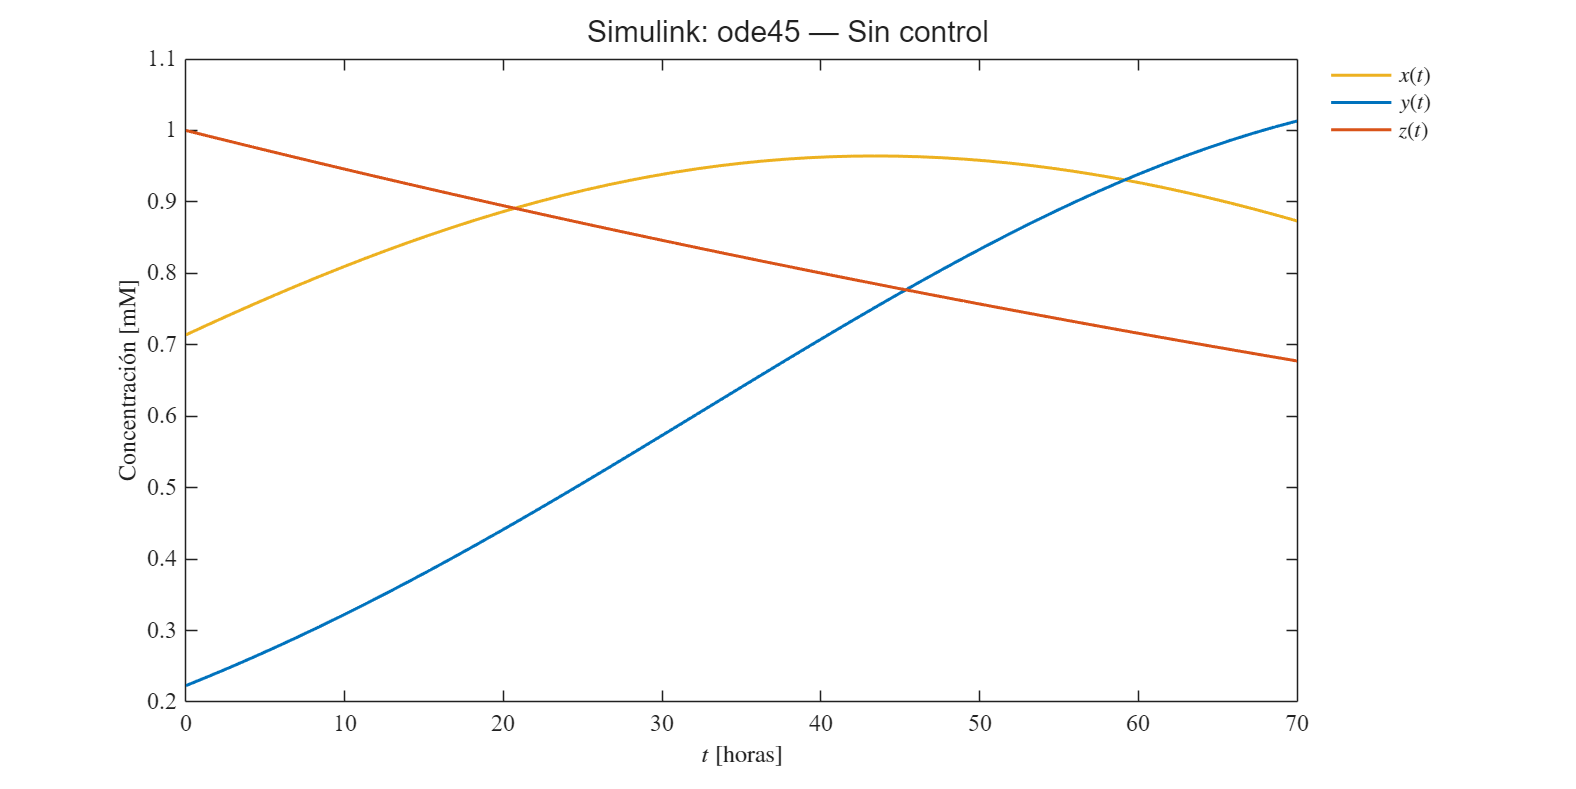

file = 'simulink';
parameters.StopTime = '70';
parameters.Solver = 'ode45';

% Sin control (u = 0)
set_param([file, '/Constant'], 'Value', '0');
f0 = sim(file, parameters);
plotedos(f0.tout, f0.x, f0.y, f0.z, par);
sgtitle('Simulink: ode45 — Sin control', 'Interpreter', 'latex');
exportgraphics(gcf,'simulink_ode45_u0.pdf','ContentType','vector')

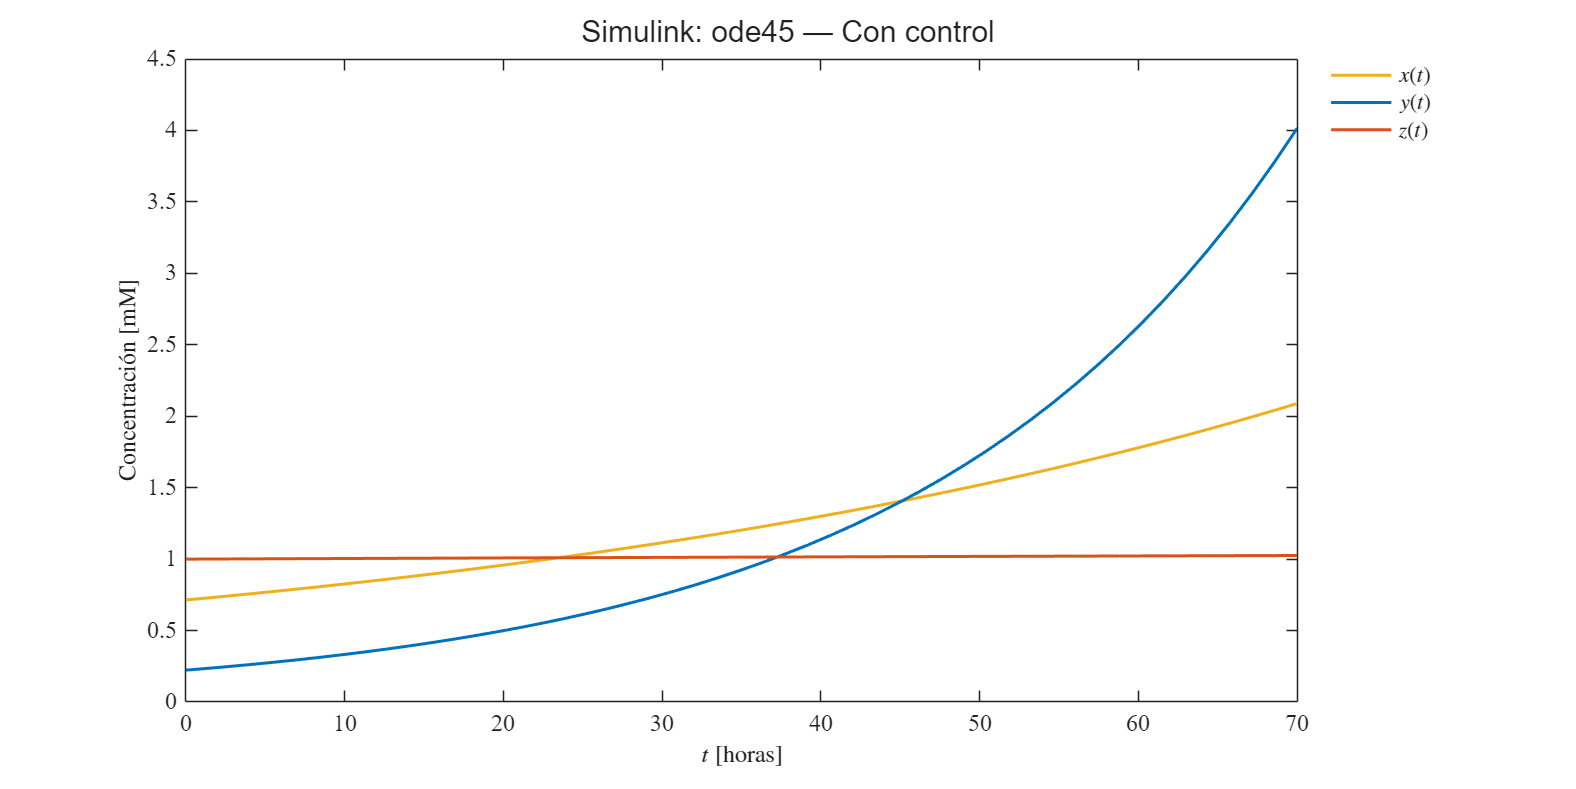

% Con control (u = 0.006)
set_param([file, '/Constant'], 'Value', '0.006');
f1 = sim(file, parameters);
plotedos(f1.tout, f1.x, f1.y, f1.z, par);
sgtitle('Simulink: ode45 — Con control', 'Interpreter', 'latex');
exportgraphics(gcf,'simulink_ode45_u006.pdf','ContentType','vector')

## Funciones

function plotsys(t,x1,y1,z1,x2,y2,z2,x3,y3,z3)

    set(figure(),'color','w')
    FS = 12;

    set(gcf,'Units','Centimeters','Position',[1,1,20,15])
    set(gca,'FontName','Times New Roman','FontSize',FS)

    % x1
    subplot(3,3,1); hold on; box on;
    plot(t,x1,'-x','LineWidth',1,'LineStyle','none','MarkerSize',5,'Color',[0 0 1])
    ylabel('$x_1 (t) [mM]$','Interpreter','latex')
    xlabel('t [horas]','Interpreter','latex')
    ylim([0 60]); yticks(0:20:60)
    xlim([0 70]); xticks(0:10:70)

    % y1
    subplot(3,3,2); hold on; box on;
    plot(t,y1,'-x','LineWidth',1,'LineStyle','none','MarkerSize',5,'Color',[0 0 1])
    ylabel('$y_1 (t) [mM]$','Interpreter','latex')
    xlabel('t [horas]','Interpreter','latex')
    ylim([0 15]); yticks(0:5:15)
    xlim([0 70]); xticks(0:10:70)

    % z1
    subplot(3,3,3); hold on; box on;
    plot(t,z1,'-x','LineWidth',1,'LineStyle','none','MarkerSize',5,'Color',[0 0 1])
    ylabel('$z_1 (t) [mM]$','Interpreter','latex')
    xlabel('t [horas]','Interpreter','latex')
    ylim([0 100]); yticks(0:20:100)
    xlim([0 70]); xticks(0:10:70)

    % x2
    subplot(3,3,4); hold on; box on;
    plot(t,x2,'-x','LineWidth',1,'LineStyle','none','MarkerSize',5,'Color',[0 0 1])
    ylabel('$x_2 (t) [mM]$','Interpreter','latex')
    xlabel('t [horas]','Interpreter','latex')
    ylim([0 4]); yticks(0:1:4)
    xlim([0 70]); xticks(0:10:70)

    % y2
    subplot(3,3,5); hold on; box on;
    plot(t,y2,'-x','LineWidth',1,'LineStyle','none','MarkerSize',5,'Color',[0 0 1])
    ylabel('$y_2 (t) [mM]$','Interpreter','latex')
    xlabel('t [horas]','Interpreter','latex')
    ylim([0 20]); yticks(0:5:20)
    xlim([0 70]); xticks(0:10:70)

    % z2
    subplot(3,3,6); hold on; box on;
    plot(t,z2,'-x','LineWidth',1,'LineStyle','none','MarkerSize',5,'Color',[0 0 1])
    ylabel('$z_2 (t) [mM]$','Interpreter','latex')
    xlabel('t [horas]','Interpreter','latex')
    ylim([0 8]); yticks(0:2:8)
    xlim([0 70]); xticks(0:10:70)

    % x3
    subplot(3,3,7); hold on; box on;
    plot(t,x3,'-x','LineWidth',1,'LineStyle','none','MarkerSize',5,'Color',[0 0 1])
    ylabel('$x_3 (t) [mM]$','Interpreter','latex')
    xlabel('t [horas]','Interpreter','latex')
    ylim([6 9]); yticks(6:1:9)
    xlim([0 70]); xticks(0:10:70)

    % y3
    subplot(3,3,8); hold on; box on;
    plot(t,y3,'-x','LineWidth',1,'LineStyle','none','MarkerSize',5,'Color',[0 0 1])
    ylabel('$y_3 (t) [mM]$','Interpreter','latex')
    xlabel('t [horas]','Interpreter','latex')
    ylim([2 8]); yticks(2:2:8)
    xlim([0 70]); xticks(0:10:70)

    % z3
    subplot(3,3,9); hold on; box on;
    plot(t,z3,'-x','LineWidth',1,'LineStyle','none','MarkerSize',5,'Color',[0 0 1])
    ylabel('$z_3 (t) [mM]$','Interpreter','latex')
    xlabel('t [horas]','Interpreter','latex')
    ylim([4 6.5]); yticks(4:0.5:6.5)
    xlim([0 70]); xticks(0:10:70)

    exportgraphics(gcf,'data.pdf','ContentType','vector')

end

function plotsys3(t,x3,y3,z3)

    set(figure(),'color','w')
    FS = 12;

    set(gcf,'Units','Centimeters','Position',[1,1,20,15])

    % x3
    subplot(3,1,1); hold on; box on;
    plot(t,x3,'-x','LineWidth',1,'LineStyle','none','MarkerSize',5,'Color',[0 0 1])
    set(gca,'FontName','Times New Roman','FontSize',FS)
    ylabel('$x_3 (t) [mM]$','Interpreter','latex')
    xlabel('t [horas]','Interpreter','latex')


    % y3
    subplot(3,1,2); hold on; box on;
    plot(t,y3,'-x','LineWidth',1,'LineStyle','none','MarkerSize',5,'Color',[0 0 1])
    set(gca,'FontName','Times New Roman','FontSize',FS)
    ylabel('$y_3 (t) [mM]$','Interpreter','latex')
    xlabel('t [horas]','Interpreter','latex')


    % z3
    subplot(3,1,3); hold on; box on;
    plot(t,z3,'-x','LineWidth',1,'LineStyle','none','MarkerSize',5,'Color',[0 0 1])
    set(gca,'FontName','Times New Roman','FontSize',FS)
    ylabel('$z_3 (t) [mM]$','Interpreter','latex')
    xlabel('t [horas]','Interpreter','latex')

end

function plotresults(to,x3o,y3o,z3o,ta,x3a,y3a,z3a)

    set(figure(),'color','w')
    FS = 12;
    set(gcf,'Units','Centimeters','Position', [1,1,20,15])
                                                    
    % x3
    subplot(3,1,1); hold on; box on;
    plot(to, x3o, 'x', 'LineWidth', 1, 'LineStyle', 'none','MarkerSize', 5, 'Color', [0 0 1], 'DisplayName', '$x_{3,o}(t)$')
    plot(ta, x3a, '-', 'LineWidth', 1.5,'Color', 'y', 'DisplayName', '$x_{3,a}(t)$')
    set(gca, 'FontName', 'Times New Roman', 'FontSize', FS)
    ylabel('$x_3(t)$ [mM]', 'Interpreter', 'latex')
    xlabel('$t$ [horas]',   'Interpreter', 'latex')
    ylim([6 9]);  yticks(6:1:9)
    xlim([0 70]); xticks(0:10:70)
    legend('Location', 'northeastoutside', 'Interpreter', 'latex'); legend boxon

    % y3
    subplot(3,1,2); hold on; box on;
    plot(to, y3o, 'x', 'LineWidth', 1, 'LineStyle', 'none','MarkerSize', 5, 'Color', [0 0 1], 'DisplayName', '$y_{3,o}(t)$')
    plot(ta, y3a, '-', 'LineWidth', 1.5,'Color', [0 0 1], 'DisplayName', '$y_{3,a}(t)$')
    set(gca, 'FontName', 'Times New Roman', 'FontSize', FS)
    ylabel('$y_3(t)$ [mM]', 'Interpreter', 'latex')
    xlabel('$t$ [horas]',   'Interpreter', 'latex')
    ylim([2 8]);  yticks(2:2:8)
    xlim([0 70]); xticks(0:10:70)
    legend('Location', 'northeastoutside', 'Interpreter', 'latex'); legend boxon

    % z3
    subplot(3,1,3); hold on; box on;
    plot(to, z3o, 'x', 'LineWidth', 1, 'LineStyle', 'none','MarkerSize', 5, 'Color', [0 0 1], 'DisplayName', '$z_{3,o}(t)$')
    plot(ta, z3a, '-', 'LineWidth', 1.5,'Color', [0 0 1], 'DisplayName', '$z_{3,a}(t)$')
    set(gca, 'FontName', 'Times New Roman', 'FontSize', FS)
    ylabel('$z_3(t)$ [mM]', 'Interpreter', 'latex')
    xlabel('$t$ [horas]',   'Interpreter', 'latex')
    ylim([4 6.5]);  yticks(4:0.5:6.5)
    xlim([0 70]);   xticks(0:10:70)
    legend('Location', 'northeastoutside', 'Interpreter', 'latex'); legend boxon

end

function plotresults2(to,x3o,y3o,z3o,ta,x3a,y3a,z3a)
    set(figure(),'color','w')
    FS = 12;
    set(gcf,'Units','Centimeters','Position',[1,1,20,15])
 
    % x3
    subplot(3,1,1); hold on; box on; grid off;
    plot(to,x3o,'x','LineWidth',1,'MarkerSize',4,'Color', 'g','DisplayName','$x_{3,o}(t)$')
    plot(ta,x3a,'-','LineWidth',1.5,'Color',[0 0 1],'DisplayName','$x_{3,a}(t)$')
    set(gca,'FontName','Times New Roman','FontSize',FS)
    xlabel('$t$ [horas]','Interpreter','latex','FontSize',FS)
    ylabel('$x_3(t)$','Interpreter','latex','FontSize',FS)
    legend('Location', 'northeastoutside', 'Interpreter', 'latex'); legend boxon
 
    % y3
    subplot(3,1,2); hold on; box on; grid off;
    plot(to,y3o,'x','LineWidth',1,'MarkerSize',4,'Color', 'g','DisplayName','$y_{3,o}(t)$')
    plot(ta,y3a,'-','LineWidth',1.5,'Color',[0 0 1],'DisplayName','$y_{3,a}(t)$')
    set(gca,'FontName','Times New Roman','FontSize',FS)
    xlabel('$t$ [horas]','Interpreter','latex','FontSize',FS)
    ylabel('$y_3(t)$','Interpreter','latex','FontSize',FS)
    legend('Location', 'northeastoutside', 'Interpreter', 'latex'); legend boxon
 
    % z3
    subplot(3,1,3); hold on; box on; grid off;
    plot(to,z3o,'x','LineWidth',1,'MarkerSize',4,'Color','g','DisplayName','$z_{3,o}(t)$')
    plot(ta,z3a,'-','LineWidth',1.5,'Color',[0 0 1],'DisplayName','$z_{3,a}(t)$')
    set(gca,'FontName','Times New Roman','FontSize',FS)
    xlabel('$t$ [horas]','Interpreter','latex','FontSize',FS)
    ylabel('$z_3(t)$','Interpreter','latex','FontSize',FS)
    legend('Location', 'northeastoutside', 'Interpreter', 'latex'); legend boxon
end

function plotedos(t, x, y, z, par)
    set(figure(),'color','w')
    FS = 12;
    set(gcf,'Units','Centimeters','Position',[1,1,30,15])

    hold on; box on; grid off;
    plot(t, x, '-', 'LineWidth', 1.5, 'Color', [0.929, 0.694, 0.125], 'DisplayName', '$x(t)$')
    plot(t, y, '-', 'LineWidth', 1.5, 'Color', [0, 0.447, 0.741],     'DisplayName', '$y(t)$')
    plot(t, z, '-', 'LineWidth', 1.5, 'Color', [0.850, 0.325, 0.098], 'DisplayName', '$z(t)$')
    set(gca,'FontName','Times New Roman','FontSize',FS)
    xlabel('$t$ [horas]', 'Interpreter', 'latex', 'FontSize', FS)
    ylabel('Concentraci\''on [mM]', 'Interpreter', 'latex', 'FontSize', FS)
    lg = legend('Interpreter', 'latex'); legend boxoff
    lg.Location = 'northeastoutside';
end

## Método de Heun

function [t,x3,y3,z3] = sysheun(x0,y0,z0,a1,a2,b1,b2,k3,tend,dt)
    n  = round(tend/dt);
    t  = (0:dt:tend)';
    x3 = zeros(length(t),1); x3(1) = x0;
    y3 = zeros(length(t),1); y3(1) = y0;
    z3 = zeros(length(t),1); z3(1) = z0;
 
    for i = 1:n
        [fx,fy,fz] = f(x3(i),y3(i),z3(i));
        xn = x3(i) + fx*dt;
        yn = y3(i) + fy*dt;
        zn = z3(i) + fz*dt;
        [fxn,fyn,fzn] = f(xn,yn,zn);
        x3(i+1) = x3(i) + (fx+fxn)*dt/2;
        y3(i+1) = y3(i) + (fy+fyn)*dt/2;
        z3(i+1) = z3(i) + (fz+fzn)*dt/2;
    end
 
    function [dx,dy,dz] = f(x,y,z)
        dx = a1*x*z - a2*x;
        dy = b1*y*z - b2*y;
        dz = -k3*z;
    end
end

## Datos experimentales

function [to,x3o,y3o,z3o] = getdata(file,smooth,normalize)
    sys = readmatrix(file);
    to  = round(sys(:,1));
    x3o = sys(:,8);
    y3o = sys(:,9);
    z3o = sys(:,10);
 
    if smooth == false && normalize == false
        return
    elseif smooth == true && normalize == false
        x3o = smoothdata(x3o,'gaussian',5);
        y3o = smoothdata(y3o,'gaussian',5);
        z3o = smoothdata(z3o,'gaussian',5);
    elseif smooth == false && normalize == true
        to  = to - to(1);
        x3o = x3o/max(x3o);
        y3o = y3o/max(y3o);
        z3o = z3o/max(z3o);
    elseif smooth == true && normalize == true
        to  = to - to(1);
        x3o = x3o/max(x3o);
        y3o = y3o/max(y3o);
        z3o = z3o/max(z3o);
        x3o = smoothdata(x3o,'gaussian',5);
        y3o = smoothdata(y3o,'gaussian',5);
        z3o = smoothdata(z3o,'gaussian',5);
    end
end


### Equilibrios

function [E, lambda] = equilibria(par)
    a1 = par(1); a2 = par(2);
    b1 = par(3); b2 = par(4);
    k3 = par(5);

    e1 = [0; 0; 0];
    E  = double(e1)';
    E(E > -1e-12 & E < 1e-12) = 0;
    x = E(1,1); y = E(1,2); z = E(1,3);
    J = [a1*z - a2, 0, a1*x;
         0, b1*z - b2, b1*y;
         0, 0, -k3 ];

    lr = real(eig(J));
    li = imag(eig(J));
    lr(lr > -1e-12 & lr < 1e-12) = 0;
    lambda = lr + 1i*li;

    stability = cell(1,1);
    if all(lr < 0)
        stability{1} = 'stable';
    elseif any(lr > 0)
        stability{1} = 'unstable';
    else
        stability{1} = 'unidentified';
    end

    fprintf('%-11s | %-9s | %-9s | %-9s|\n','Equilibria',' x*',' y*',' z*');
    fprintf('-------------------------------------------------\n');
    fprintf('%-10s (%10.3e ,%10.3e ,%10.3e)\n', 'eq1', E(1), E(2), E(3));
    fprintf('\n\n%-10s | %-16s | %-16s | %-16s| %-10s|\n','Equilibria',' lambda 1',' lambda 2',' lambda 3','stability');
    fprintf('---------------------------------------------------------------------------------\n');
    fprintf('%-10s %+.1e%+.1ei %+.1e%+.1ei %+.1e%+.1ei %-10s\n', 'eq1', ...
        real(lambda(1)), imag(lambda(1)), ...
        real(lambda(2)), imag(lambda(2)), ...
        real(lambda(3)), imag(lambda(3)), ...
        stability{1});
end